%Record data using CoolTerm program

% Import photoresistor data from text
% file using Home->Import Data.  Import as column vector. 
% Do not import Nan Rows.

%Estimate sample frequency (Fs) from timestamps
Fs=44100;
CTvoltage=y(1:11*44100,1);

CTvoltage =          0
         0
         0
    0.3052
         0
         0
         0
         0
         0
         0


%Define Recording Length (seconds)
L=length(CTvoltage)/Fs;

y=CTvoltage(1:end-2,1);


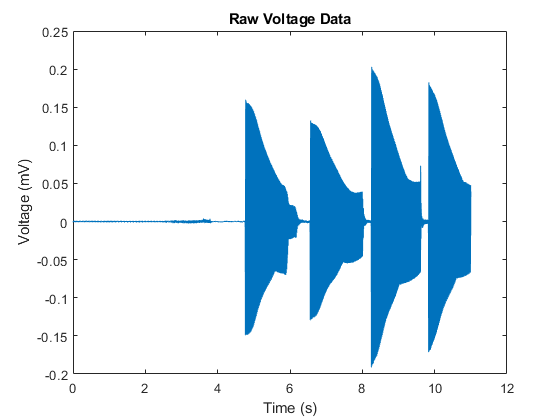

%Perform FFT Analysis
%Calculate time values
tt=linspace(0,L,length(y));

%Plot Raw Data
plot(tt,y);
title('Raw Voltage Data')
xlabel('Time (s)');ylabel('Voltage (mV)');

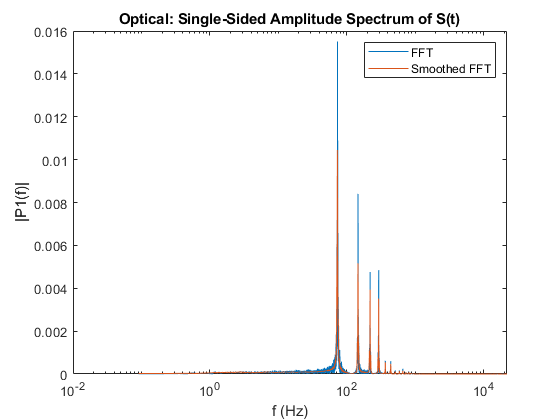


% Smooth voltage data
%y=smoothdata(y,'gaussian',[0 10]);
%Plot Smoothed Data
%plot(tt,y); title('Smoothed Voltage Data');
%xlabel('Time (s)');ylabel('Voltage (mV)');

%Compute FFT
Y=fft(y);
L=Fs*L;

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

%Define frequency domain and plot
f = Fs*(0:(L/2))/L;

%sgf_0=sgolayfilt(P1,21,75);
semilogx(f,P1);hold on; %semilogx(f,sgf_0,'red');
semilogx(f,smoothdata(P1,'movmean',[0 5])); hold off;
title('Optical: Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)'); ylabel('|P1(f)|'); legend('FFT','Smoothed FFT');


%Filter signal (Bandpass 20-22050 Hz)
bandpass_y = bandpass(y,[20 22050],Fs);

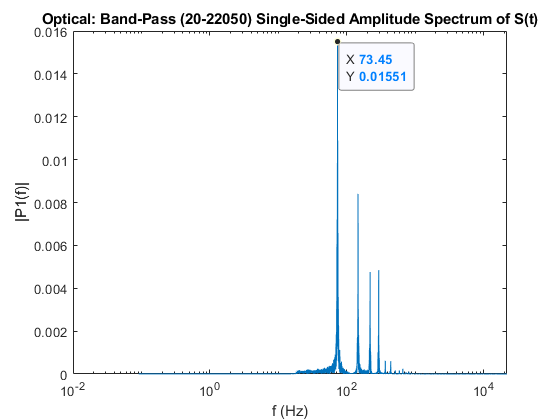

%Compute filtered FFT
bandpass_Y=fft(bandpass_y);
bandpass_P2 = abs(bandpass_Y/L);
bandpass_P1 = bandpass_P2(1:L/2+1);
bandpass_P1(2:end-1) = 2*bandpass_P1(2:end-1);

%sgf=sgolayfilt(bandpass_P1,21,75);
semilogx(f,bandpass_P1); hold on; %semilogx(f,sgf,'green') 
title('Optical: Band-Pass (20-22050) Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')


%sgf2=smoothdata(sgf,'movmean',[0 12]);
%semilogx(f,sgf2,'red')
%legend('FFT','SGF','Smoothed SGF')